 Written by Mark Marner-Hausen

clc
clear
close all
format long

# Part 2: Wealth and Constructed Wealth Shocks

% Load data from previous part 
CurrentWealth = readtable('CurrentWealth.csv');
LifeTimeWealth = readtable('LifeTimeWealth.csv');
sample = readtable('sample.csv');
HwAstck = readtable('HwAstck.csv');
HhId = readtable('HhId.csv');

CurrentWealth = table2array(CurrentWealth);
LifeTimeWealth = table2array(LifeTimeWealth);

sample = table2array(sample);
sample = logical(sample);

HwAstck = table2array(HwAstck);

HhId = table2array(HhId);
HhId = str2double(HhId);

% Calculate total stock wealth
H98_ira = readtable('H98_ira.csv');
H98_irap = readtable('H98_irap.csv');
HhId98 = readtable('HhId98.csv');

H00_ira = readtable('H00_ira.csv');
H00_irap = readtable('H00_irap.csv');
HhId00 = readtable('HhId00.csv');

H02_ira = readtable('H02_ira.csv');
H02_irap = readtable('H02_irap.csv');
HhId02 = readtable('HhId02.csv');

H04_ira = readtable('H04_ira.csv');
H04_irap = readtable('H04_irap.csv');
HhId04 = readtable('HhId04.csv');

H06_ira = readtable('H06_ira.csv');
H06_irap = readtable('H06_irap.csv');
HhId06 = readtable('HhId06.csv');

H08_ira = readtable('H08_ira.csv');
H08_irap = readtable('H08_irap.csv');
HhId08 = readtable('HhId08.csv');

H10_ira = readtable('H10_ira.csv');
H10_irap = readtable('H10_irap.csv');
HhId10 = readtable('HhId10.csv');



H98_ira = table2array(H98_ira);
H98_irap = table2array(H98_irap);
HhId98 = table2array(HhId98);
HhId98 = str2double(HhId98);

H00_ira = table2array(H00_ira);
H00_irap = table2array(H00_irap);
HhId00 = table2array(HhId00);
HhId00 = str2double(HhId00);

H02_ira = table2array(H02_ira);
H02_irap = table2array(H02_irap);
HhId02 = table2array(HhId02);
HhId02 = str2double(HhId02);

H04_ira = table2array(H04_ira);
H04_irap = table2array(H04_irap);
HhId04 = table2array(HhId04);
HhId04 = str2double(HhId04);

H06_ira = table2array(H06_ira);
H06_irap = table2array(H06_irap);
HhId06 = table2array(HhId06);
HhId06 = str2double(HhId06);

H08_ira = table2array(H08_ira);
H08_irap = table2array(H08_irap);
HhId08 = table2array(HhId08);
HhId08 = str2double(HhId08);

H10_ira = table2array(H10_ira);
H10_irap = table2array(H10_irap);
HhId10 = table2array(HhId10);
HhId10 = str2double(HhId10);

H98_ira(ismissing(H98_ira)) = 0;
H98_irap(ismissing(H98_irap)) = 0;

H00_ira(ismissing(H00_ira)) = 0;
H00_irap(ismissing(H00_irap)) = 0;

H02_ira(ismissing(H02_ira)) = 0;
H02_irap(ismissing(H02_irap)) = 0;

H04_ira(ismissing(H04_ira)) = 0;
H04_irap(ismissing(H04_irap)) = 0;

H06_ira(ismissing(H06_ira)) = 0;
H06_irap(ismissing(H06_irap)) = 0;

H08_ira(ismissing(H08_ira)) = 0;
H08_irap(ismissing(H08_irap)) = 0;

H10_ira(ismissing(H10_ira)) = 0;
H10_irap(ismissing(H10_irap)) = 0;

tmp_leng = length(LifeTimeWealth);
Amount_Sample = length(nonzeros(sample));

StockIra = cell(7,2);
StockIra{1,1} = sum(H98_ira .* H98_irap .* (1/100),2);
StockIra{2,1} = sum(H00_ira .* H00_irap .* (1/100),2);
StockIra{3,1} = sum(H02_ira .* H02_irap .* (1/100),2);
StockIra{4,1} = sum(H04_ira .* H04_irap .* (1/100),2);
StockIra{5,1} = sum(H06_ira .* H06_irap .* (1/100),2);
StockIra{6,1} = sum(H08_ira .* H08_irap .* (1/100),2);
StockIra{7,1} = sum(H10_ira .* H10_irap .* (1/100),2);

StockIra{1,2} = HhId98;
StockIra{2,2} = HhId00;
StockIra{3,2} = HhId02;
StockIra{4,2} = HhId04;
StockIra{5,2} = HhId06;
StockIra{6,2} = HhId08;
StockIra{7,2} = HhId10;



StockIraL = zeros(tmp_leng,7);
for j = 1:7
    StockIra_tmp1 = StockIra{j,1};
    StockIra_tmp2 = StockIra{j,2};
    for i = 1:length(StockIra_tmp1)
        
            tmp = HhId(:,1) == StockIra_tmp2(i,1) &...
            HhId(:,2) == StockIra_tmp2(i,2) ;
        
            StockIraL(tmp,j) = StockIra_tmp1(i);
            
    end
end
StockWealth = [zeros(length(StockIraL),1) StockIraL ];

StockWealth = StockWealth + HwAstck;
StockWealth(ismissing(StockWealth)) = 0;


% Construct wealth shocks
sp_monthly = readtable('sp_monthly.csv');
sp_monthly_TotalReturn = readtable('sp_monthly_TotalReturn.csv');
urateUSnat = readtable('urateUSnat.csv');

sp_monthly = table2array(sp_monthly);
sp_monthly_TotalReturn = table2array(sp_monthly_TotalReturn);


% Percentage change in S&P500 between 2 waves
sp_change = zeros(8,2);

sp_change(1,1) = 1998;

sp_change(8,1) = 9999;
tmp1 = sum(sp_monthly(85:96,2))/12;
tmp2 = sum(sp_monthly(229:240,2))/12;
sp_change(8,2) = (tmp2 - tmp1) / tmp1;
 
k =2;
for i = 85:24:216
         
            sp_change(k,1) = sp_change(k-1,1) + 2;
            
            tmp1 = sum(sp_monthly(i:i+11,2))/12;
            tmp2 = sum(sp_monthly(i+24:i+35,2))/12;
            
            sp_change(k,2) = (tmp2 - tmp1) / tmp1;

            k = k + 1;

end


% Percentage change in S&P500 between 2 waves exact

sp_exact = zeros(12,6);
k=1;
for i = 85:24:216
    
    sp_exact(:,k) = (sp_monthly(i+24:i+35,2) - sp_monthly(i:i+11,2))/sp_monthly(i+11,2);
    k = k+1;
end

% Share of lifetime wealth in stocks
ShareLTWinStocks = StockWealth ./ LifeTimeWealth; 
ShareLTWinStocks(ismissing(ShareLTWinStocks)) = 0;
ShareLTWinStocks(ShareLTWinStocks > 1) = 0;
ShareLTWinStocks(ShareLTWinStocks < 0) = 0;

shocks = zeros(tmp_leng,8);
for i = 1:6
     shocks(:,i+2) = ShareLTWinStocks(:,i+1) * sp_change(i+1,2);
 
 end

 
% Shocks should be in [-1,1], I discovered outliers 
% distorting the data, therefore: 
shocks(shocks > 1) = 1;
shocks(shocks < -1) = -1;




% Summary Statistics Wealth Measures Data
% Summary Statistics Wealth Measures analysis
SLifeTimeWealth = zeros(8,1);
SLifeTimeWealth(8,1) = sum(LifeTimeWealth(sample))/Amount_Sample;

SCurrentWealth = zeros(8,1);
SCurrentWealth(8,1) = sum(CurrentWealth(sample))/Amount_Sample;

SStockWealth = zeros(8,1);
SStockWealth(8,1) = length(nonzeros(StockWealth(sample)))...
                    /Amount_Sample;

SSLS = zeros(8,1);
SSLS(8,1) = sum(ShareLTWinStocks(sample))...
            /length(nonzeros(ShareLTWinStocks(sample)));

                 
                    
Ssp_change = sp_change(:,2);

                
SSchocks = zeros(8,1);
SSchocks(8,1) = sum(shocks(sample))...
                /length(shocks(sample));



for i= 2:8
    tmp = StockWealth(:,i);
    tmp1 = LifeTimeWealth(:,i);
    tmp2 = CurrentWealth(:,i);
    tmp3 = ShareLTWinStocks(:,i);
    tmp4 = shocks(:,i);
 
    SStockWealth(i-1) = length(nonzeros(tmp(sample(:,i))))...
                        /sum(sample(:,i));
                    
    SLifeTimeWealth(i-1) = sum(tmp1(sample(:,i)))/sum(sample(:,i));
    
    SCurrentWealth(i-1) = sum(tmp2(sample(:,i)))/sum(sample(:,i));
    
    SSLS(i-1) = sum(tmp3(sample(:,i)))...
                /length(nonzeros(tmp3(sample(:,i))));
    
    SSchocks(i-1) = sum(tmp4(sample(:,i)))...
                     /length(nonzeros(tmp4(sample(:,i))));
         
end


Mean = [    transpose(SCurrentWealth);
            transpose(SLifeTimeWealth);
            transpose(SStockWealth);
            transpose(SSLS);
            transpose(Ssp_change);
            transpose(SSchocks)];

T4 = table(Mean);
T4.Properties.RowNames = ["CW","LTW","SW","SLS" ...
    ,"SpChange","Shocks"]

T4 = 6×1 table
                    Mean    
                ____________

    CW          [1x8 double]
    LTW         [1x8 double]
    SW          [1x8 double]
    SLS         [1x8 double]
    SpChange    [1x8 double]
    Shocks      [1x8 double]


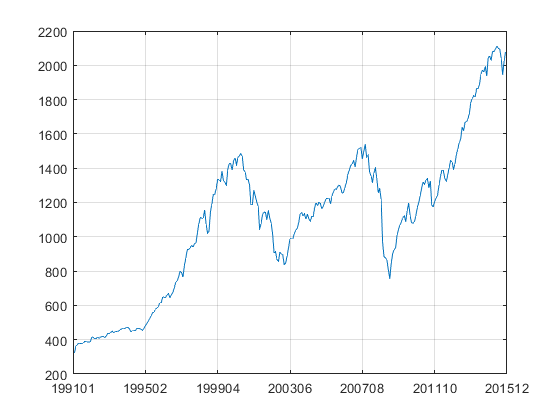

x = 1:299;
y = sp_monthly(1:299,2);


plot(x,y)
set(gca,'XGrid','on','YGrid','on', ...
    'xticklabel', [199101 199502 199904 ...
    200306 200708 201110 201512 ])

csvwrite('StockWealth.csv',StockWealth);
csvwrite('ShareLTWinStocks.csv',ShareLTWinStocks);
csvwrite('sp_exact.csv',sp_exact);
csvwrite('shocks.csv',shocks);
